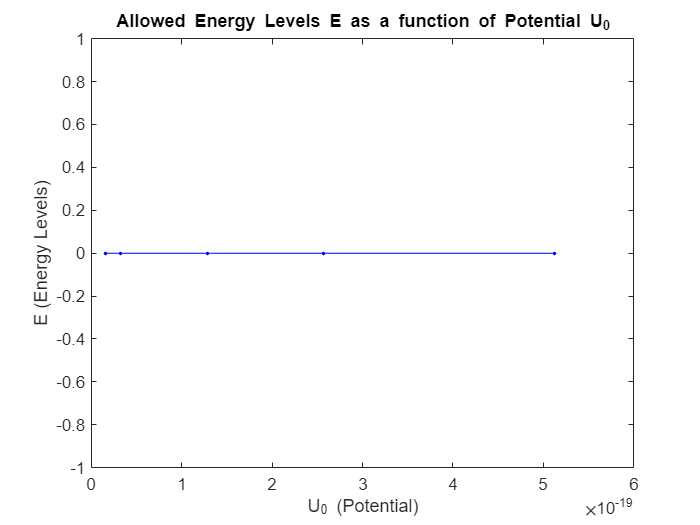

% Define the potential barrier heights (in eV)
barrier_heights = [0.1*eV, 0.2*eV, 0.8*eV, 1.6*eV, 3.2*eV];

% Results from exercise (a) in eV
analitical_results=[0.0561239038617234,0.224495615446894,0.505115134755511,0.897982461787575,1.40309759654309,2.02046053902204,2.75007128922445,3.5919298471503,4.5460362127996,5.61239038617234];

% Placeholder for eigenstate energies calculation
% In reality, this would involve solving the Schrödinger equation for each barrier
num_states = 5;  % number of eigenstates for illustration

a=10e-9; % Width of the well
m_eff=0.067; % Ratio of the mass
m_e = 9.10938356e-31; % electron rest mass, in kg
m=m_eff * m_e; % Effective mass of the electron
h_bar = 1.0545718e-34; % Planck's constant over 2*pi, in J*s
eV = 1.602176634e-19; % Joule per eV

% Initialize an array to hold the energies
eigenstate_energies = zeros(num_states, length(barrier_heights));

% Calculate eigenstate energies for each barrier height
% This is a placeholder. Replace with the actual calculation method
for i = 1:length(barrier_heights)
    for n = 1:num_states
        wavelength = 2 * a / n; % Considering that the lenght L = (n x wavelentgh) / 2
        wavenumber = (2 * pi) / wavelength;
        % Example calculation, replace with actual Schrödinger equation solution
        eigenstate_energies(n, i) = barrier_heights(i)-((hbar^2 * wavenumber^2 / (2 * m))/eV);
    end
end

% Plot the result
figure;
plot(U_0_values, E_levels, 'b.-');
xlabel('U_0 (Potential)');
ylabel('E (Energy Levels)');
title('Allowed Energy Levels E as a function of Potential U_0');


% Plotting
figure;
hold on;
for n = 1:num_states
    plot(barrier_heights, eigenstate_energies(n, :), 'O-', 'DisplayName', ['State ' num2str(n)]);
end
% Add a horizontal line for the analytical result (placeholder value)
for j = 1:length(analitical_results)
    analitical_results(:,j)
    yline(analitical_results(:,j), '--', append('Analitical from n=',int2str(j)), 'LabelHorizontalAlignment','left', 'HandleVisibility', 'off');  % Replace '1' with the actual analytical result value
end

ans = 0.0561

ans = 0.2245

ans = 0.5051

ans = 0.8980

ans = 1.4031

ans = 2.0205

ans = 2.7501

ans = 3.5919

ans = 4.5460

ans = 5.6124

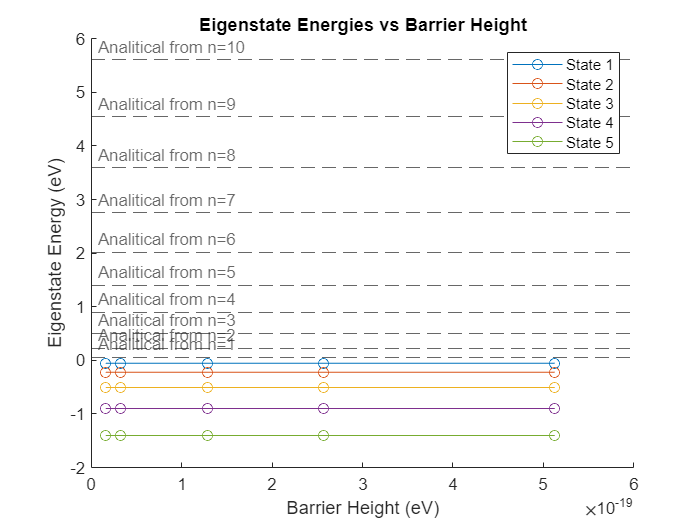

hold off;
xlabel('Barrier Height (eV)');
ylabel('Eigenstate Energy (eV)');
title('Eigenstate Energies vs Barrier Height');
legend;

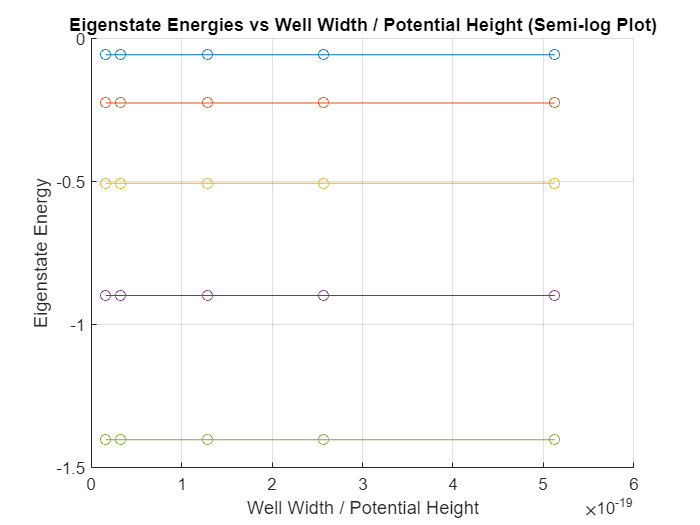


% Create a semi-log plot
figure;
hold on;
for n = 1:num_states
    semilogy(barrier_heights, eigenstate_energies(n, :), 'O-', 'DisplayName', ['State ' num2str(n)]);
end
xlabel('Well Width / Potential Height');
ylabel('Eigenstate Energy');
title('Eigenstate Energies vs Well Width / Potential Height (Semi-log Plot)');
grid on;